images_dark=loadRAWin3dMatrix_mono('D:\Luis\Documents\EIT_HS-Düsseldorf\Semester 6\EMVA1288_SimDataforVerification\Mono640x480_12bit_dsnu',640,480);
images_50=loadRAWin3dMatrix_mono('D:\Luis\Documents\EIT_HS-Düsseldorf\Semester 6\EMVA1288_SimDataforVerification\Mono640x480_12bit_prnu',640,480);
image_mv=loadRAWin3dMatrix_mono('D:\Luis\Documents\EIT_HS-Düsseldorf\Semester 6\EMVA1288_SimDataforVerification\Mono640x480_12bit_mv',640,480);

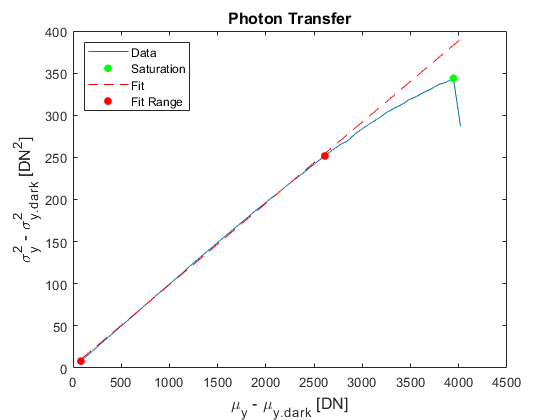

[mean_dark,var_dark,K]=photonTransfer_curve_EMVA1288_mono_3dMatrix(image_mv);

temp_dark_noise=compute_temporaldarknoise(var_dark,(1/12),K);

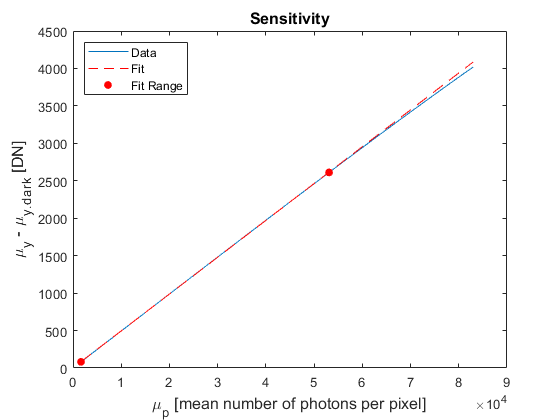

[R,p_sat]=sensitivity_curve_mono_3dMatrix(image_mv,1659.66);

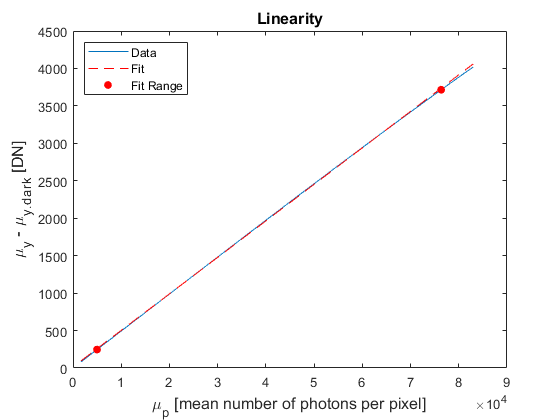

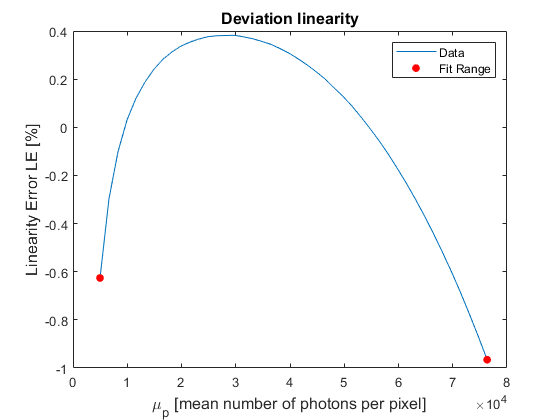

[LE_min,LE_max] = linearity_3dMatrix(image_mv,1659.66);

[DSNU,PRNU,sv_50,sv_dark,avg_img_dark,avg_img_50,var_stack_dark,var_stack_50] = DSNU_PRNU_3dmat(images_dark,images_50,K);

p_min=absolute_sensitivity_threshold(R/K,var_dark,K);
e_sat=saturation_capacity(R/K,p_sat);

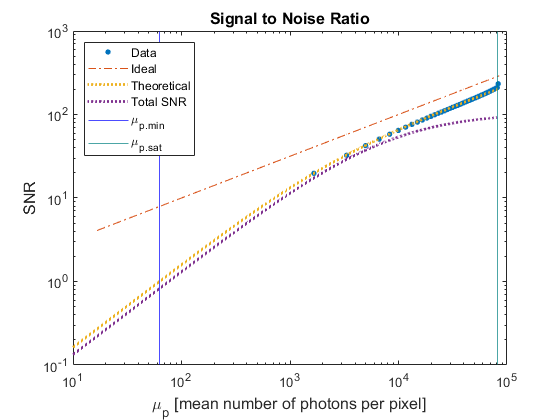

[SNR_max,DR] = plot_SNR_3dMatrix(image_mv,1659.66,p_min,p_sat,e_sat,temp_dark_noise,1/12,K,R/K,DSNU,PRNU);

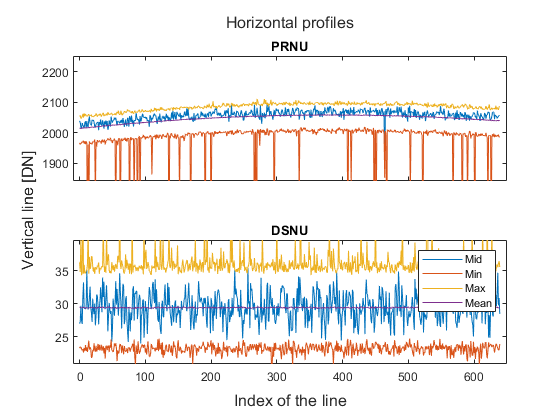

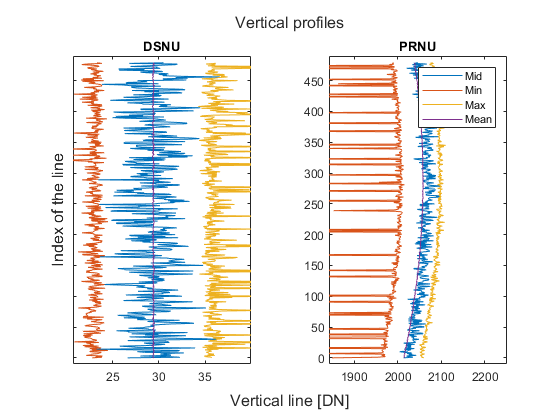

profiles(avg_img_dark,avg_img_50);

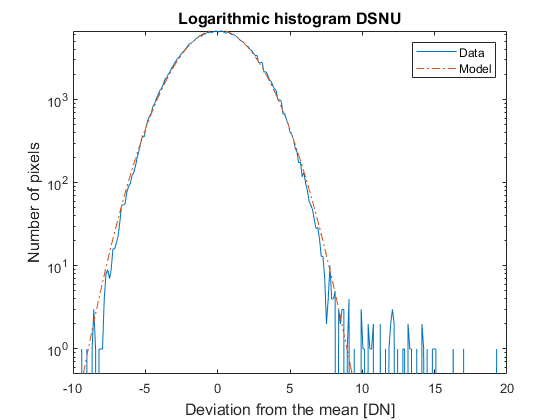

logarithmic_histogram_DSNU(avg_img_dark,100,sv_dark);

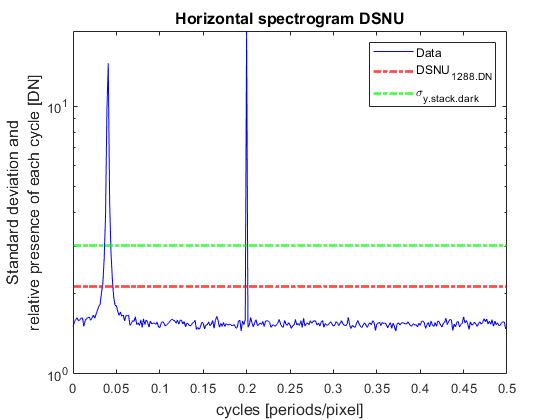

[spatial_var_whitenoise_DSNU_hor] = spectrogram(avg_img_dark,avg_img_50,'horizontal','DSNU',DSNU,var_stack_dark,K);

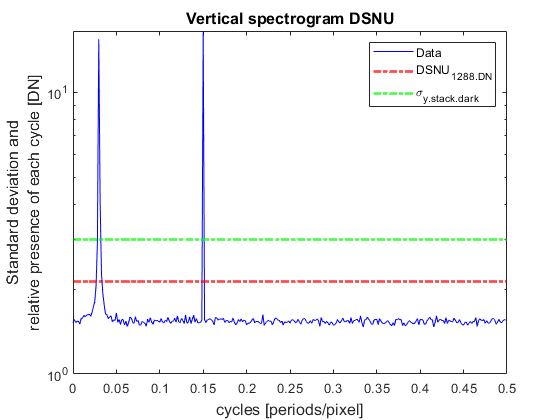

[spatial_var_whitenoise_DSNU_vert] = spectrogram(avg_img_dark,avg_img_50,'vertical','DSNU',DSNU,var_stack_dark,K);

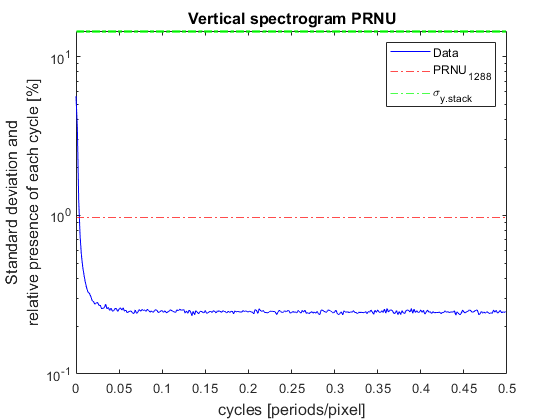

[spatial_var_whitenoise_PRNU_vert] = spectrogram(avg_img_dark,avg_img_50,'vertical','PRNU',PRNU,var_stack_50,K);

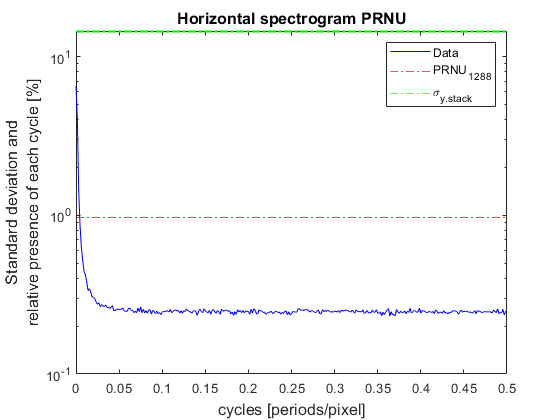

[spatial_var_whitenoise_PRNU_hor] = spectrogram(avg_img_dark,avg_img_50,'horizontal','PRNU',PRNU,var_stack_50,K);